parallel.gpu.enableCUDAForwardCompatibility(true)

ir_len = 128;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

[target, ref] = recorded_samples();

filter_order = ir_len * 2;
n_iter = 3;

% mu = 0.05;
% fxlms = FxLMS(ref, target, panel_ir, filter_order, mu);
% fxlms.gpu = false;

% [pred, mses] = fxlms.learn(n_iter, true);

% figure
% plot(mses);

lamda = 0.999;
cov_scale = 0.1

cov_scale = 0.1000

fxrls_small = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);

fxrls_small.gpu = false;

[pred_small, mses_small] = fxrls_small.learn(n_iter, true);

Iteration 1/3
Iteration 2/3
Iteration 3/3


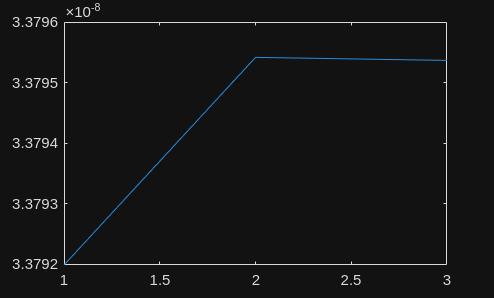

figure
plot(mses_small);

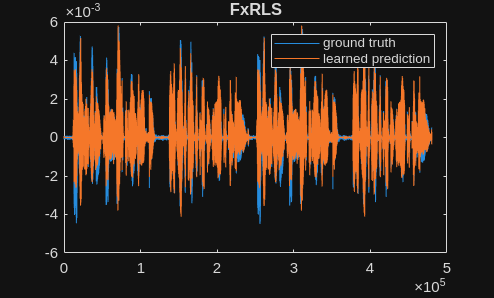

fxrls_small.results_plot()

ir_len = 1024;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

filter_order = ir_len * 2;
n_iter = 2;

fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);
fxrls.gpu = true;

[pred, mses] = fxrls.learn(n_iter, true);

Iteration 1/2
Iteration 2/2


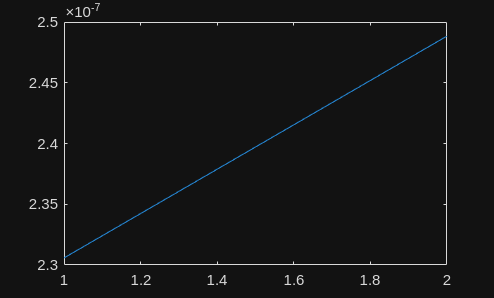

figure
plot(mses);

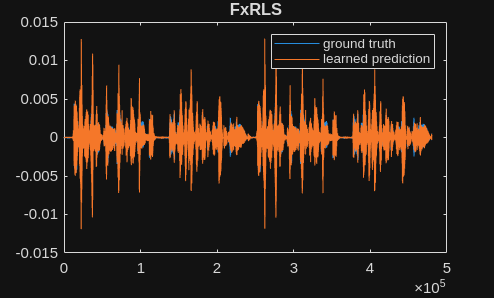

fxrls.results_plot()

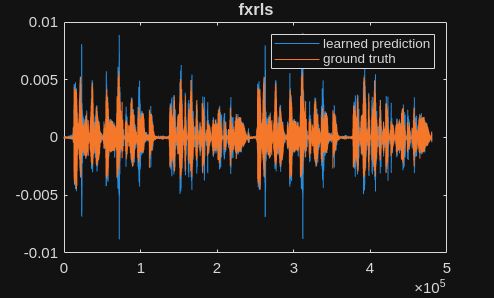

figure
plot(pred)
hold on
plot(target)
legend('learned prediction', 'ground truth')
title('fxrls')